### Theoretical Path

% define equation of potential field
syms x y
z_total = 0;
a_divot = -2;
a_barrel = 30;
a_wall = -10;
numPoints = 30;

% top right obstacle
z_total = makeDivot([-0.25 -1], z_total, a_divot);


% bottom right obstacle
z_total = makeDivot([1 -0.7], z_total, a_divot);


% bottom left obstacle
z_total = makeDivot([1.41 -2], z_total, a_divot);


% BoB
z_total = makeDivot([0.75 -2.5], z_total, a_barrel);

% top right corner
z_total = makeDivot([-1.5 1], z_total, a_wall);

% bottom right wall
z_total = makeDivot([2.5 1], z_total, a_wall);

% top left wall
z_total = makeDivot([-1.5 -3.37], z_total, a_wall);

% bottom left wall
z_total = makeDivot([2.5 -3.37], z_total, a_wall);


% define meshgrid for plotting
clf
[X,Y] = meshgrid(linspace(-1.5,2.5,50),linspace(-3.37,1,50));
Z = double(subs(z_total,{x,y},{X,Y}));

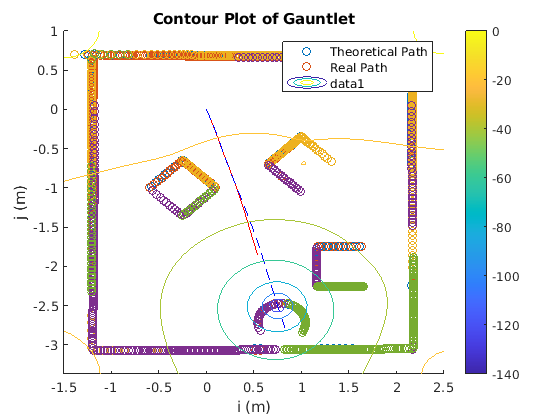

% plot contour
hold off

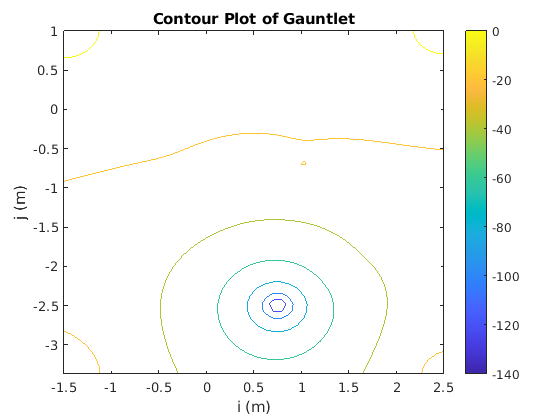

figure
contour(X,Y,Z)
title("Contour Plot of Gauntlet")
xlabel('i (m)')
ylabel('j (m)')
zlabel('k (m)')
colorbar

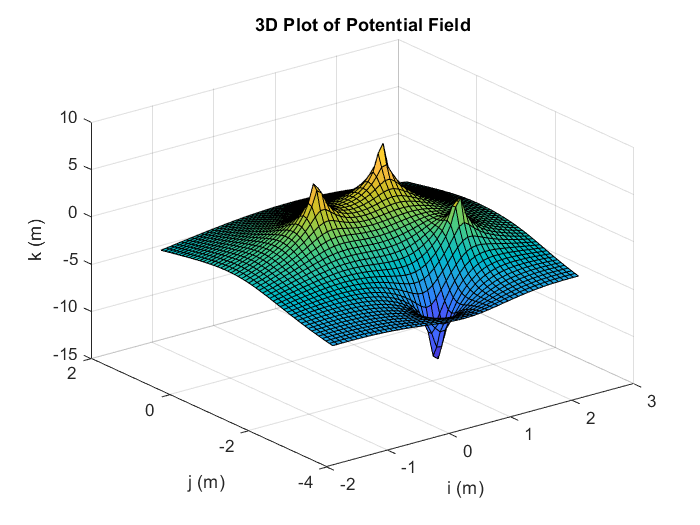

% plot 3D potential field
surf(X,Y,Z)
title("3D Plot of Potential Field")
xlabel('i (m)')
ylabel('j (m)')
zlabel('k (m)')

% perform gradient descent
[position, positions] = flatland_assignment(z_total);

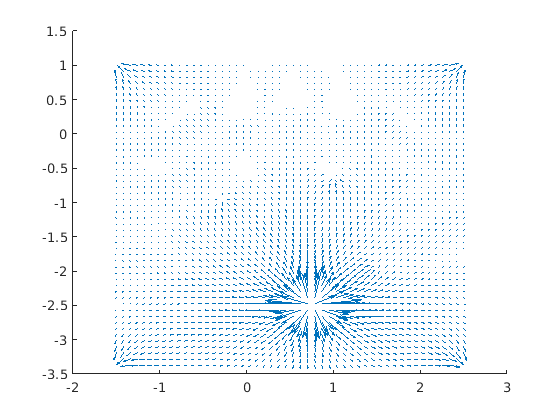

% gradient vector plot
[px, py] = gradient(Z);
figure
quiver(X, Y, px, py, 4)
hold off

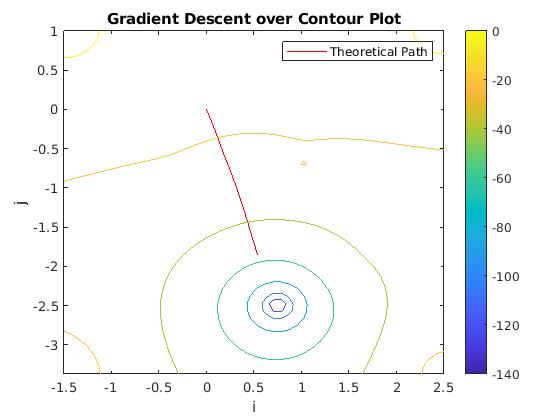

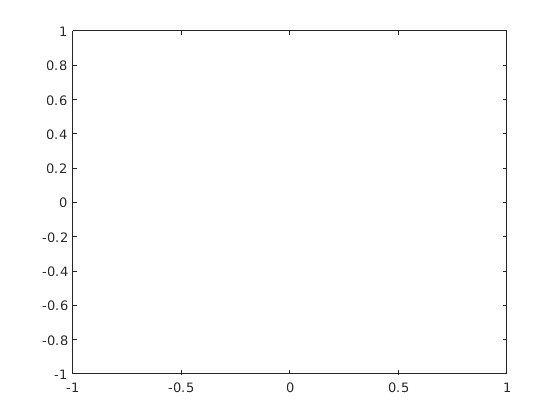

% plot the theoretical gradient descent with contour plot
figure
plot(positions(:, 1), positions(:, 2), "-r")
hold on
contour(X,Y,Z)
colorbar
xlabel('i')
ylabel('j')
title("Gradient Descent over Contour Plot")
legend("Theoretical Path")

### Real Path

% get and interpret encoder data
data = readtable("my_data.csv");

data = data(1:192, :);
data.time_seconds_ = data.time_seconds_ - 6.301;
start = [0 0];
start_theta = 0;

diff_time = diff(data.time_seconds_);
diff_vl = diff(data.encoderLeft_meters_);
diff_vr = diff(data.encoderRight_meters_);

vl_actual = diff_vl ./ diff_time;
vr_actual = diff_vr ./ diff_time;

ang_vel = (vr_actual - vl_actual) / .235;
delta_ang = ang_vel .* diff_time;
vel = (vl_actual + vr_actual) / 2;

delta_dist = vel .* diff_time;

values = zeros(150, 3);
temp = zeros(150, 1);
temp(1, 1) = start_theta;
temp(2:192, 1) = delta_ang;
delta_ang = temp;
delta_ang = cumsum(delta_ang);

cos_vals = cos(delta_ang(2:192, 1));
sin_vals = sin(delta_ang(2:192, 1));
x_part = delta_dist .* cos_vals;
y_part = delta_dist .* sin_vals;

values(1, 2:3) = start;
values(2:192, 2) = x_part;
values(2:192, 3) = y_part;

values = cumsum(values);

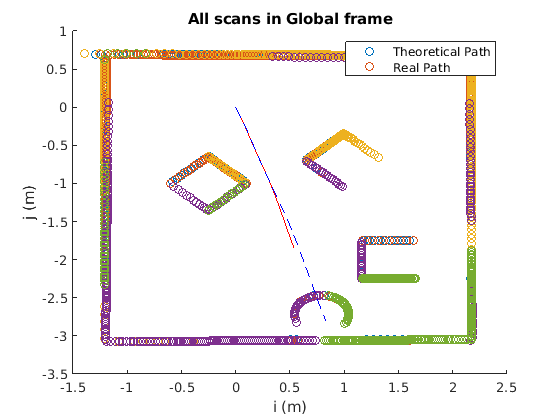

% plot real and theoretical paths
hold off

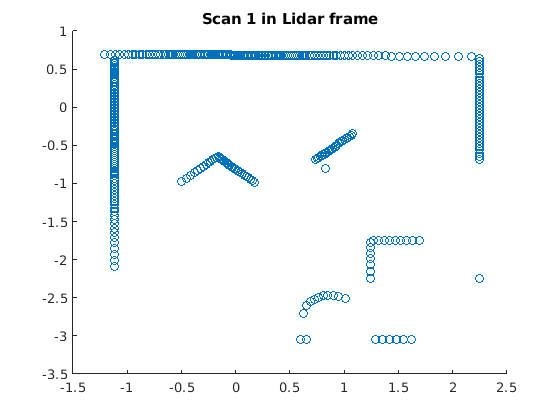

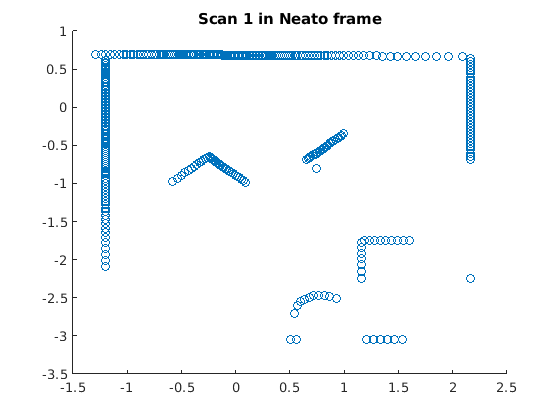

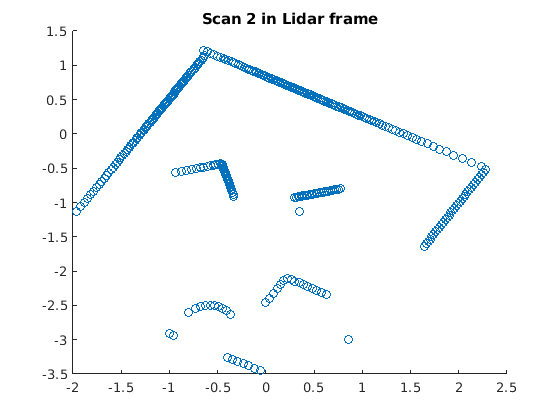

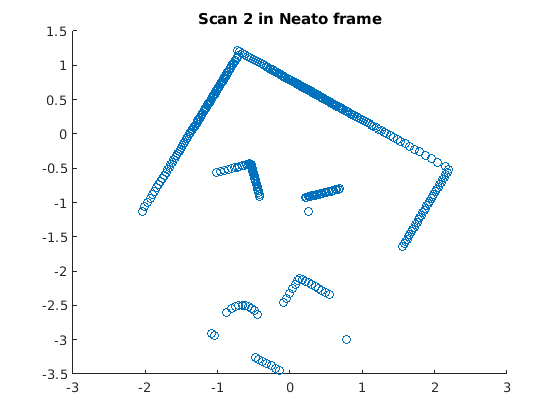

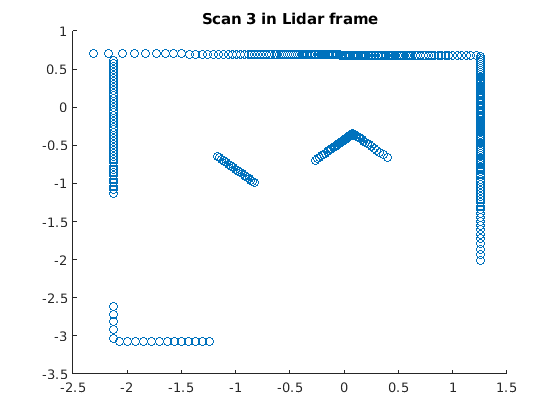

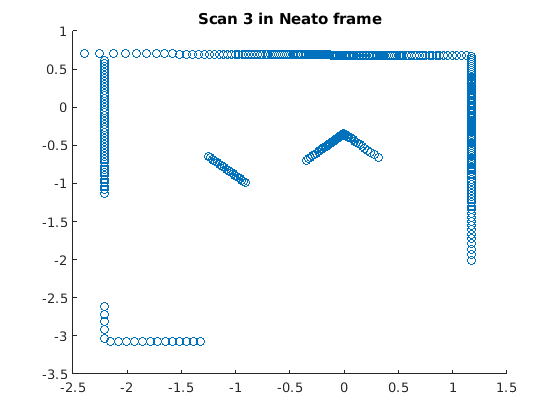

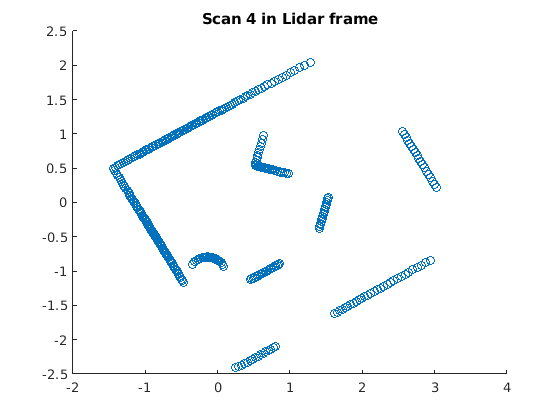

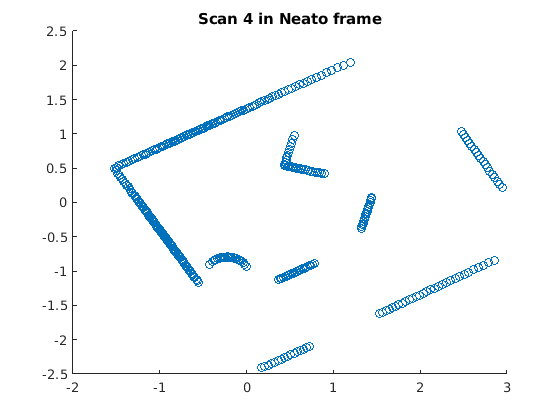

makeMap();

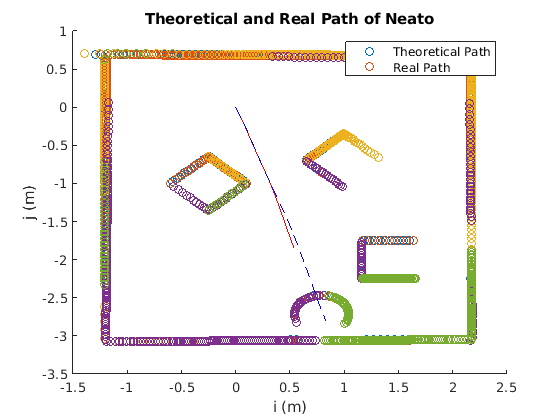

hold on 
plot(positions(:, 1), positions(:, 2), "-r")
plot(values(:, 2), values(:, 3), "--b")
xlabel('i (m)')
ylabel('j (m)')
title("Theoretical and Real Path of Neato")
legend("Theoretical Path", "Real Path")